auto=readtable("auto_clean.csv")

auto = 201×29 table
    symboling    normalized_losses         make          aspiration    num_of_doors      body_style       drive_wheels    engine_location    wheel_base    length      width     height    curb_weight    engine_type    num_of_cylinders    engine_size    fuel_system    bore    stroke    compression_ratio    horsepower    peak_rpm    city_mpg    highway_mpg    price    city_L_100km    horsepower_binned    diesel    gas
    _________    _________________    _______________    __________    ____________    _______________    ____________    _______________    __________    _______    _______    ______    ___________    ___________    ________________    ___________    ___________    ____    ______    _________________    __________    ________    ________    ___________    _____    ____________    _________________    ______    ___

        3               122           {'alfa-romero'}    {'std'  }       {'two' }      {'convertible'}      {'rwd'}          {'front'}       


auto_summary=summary(auto)

auto_summary = 包含以下字段的 struct :
            symboling: [1×1 struct]
    normalized_losses: [1×1 struct]
                 make: [1×1 struct]
           aspiration: [1×1 struct]
         num_of_doors: [1×1 struct]
           body_style: [1×1 struct]
         drive_wheels: [1×1 struct]
      engine_location: [1×1 struct]
           wheel_base: [1×1 struct]
               length: [1×1 struct]
                width: [1×1 struct]
               height: [1×1 struct]
          curb_weight: [1×1 struct]
          engine_type: [1×1 struct]
     num_of_cylinders: [1×1 struct]
          engine_size: [1×1 struct]
          fuel_system: [1×1 struct]
                 bore: [1×1 struct]
               stroke: [1×1 struct]
    compression_ratio: [1×1 struct]
           horsepower: [1×1 struct]
             peak_rpm: [1×1 struct]
             city_mpg: [1×1 struct]
          highway_mpg: [1×1 struct]
                price: [1×1 struct]
         city_L_100km: [1×1 struct]
    horsepower_binned: [1×1 stru

auto_summary.price

ans = 包含以下字段的 struct :
           Size: [201 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 5118
         Median: 10295
            Max: 45400
     NumMissing: 0


mean(auto.price)

ans = 1.3207e+04

std(auto.price)

ans = 7.9471e+03

## box plot

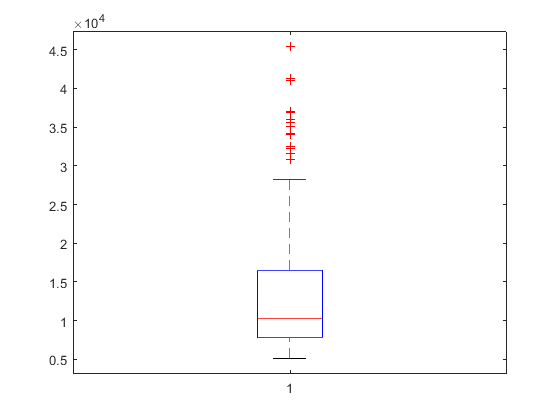

boxplot(auto.price)

## histogram

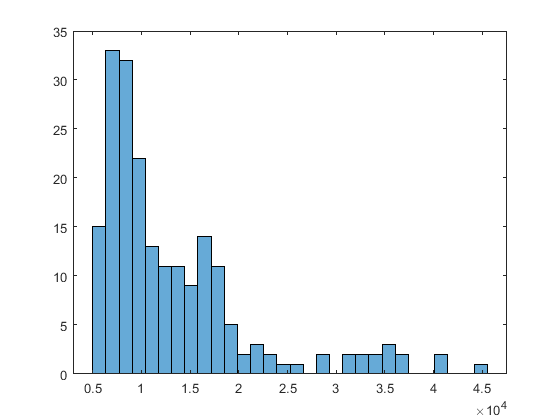

histogram(auto.price,30)

## categorical

auto.body_style=categorical(auto.body_style)

auto = 201×29 table
    symboling    normalized_losses         make          aspiration    num_of_doors    body_style     drive_wheels    engine_location    wheel_base    length      width     height    curb_weight    engine_type    num_of_cylinders    engine_size    fuel_system    bore    stroke    compression_ratio    horsepower    peak_rpm    city_mpg    highway_mpg    price    city_L_100km    horsepower_binned    diesel    gas
    _________    _________________    _______________    __________    ____________    ___________    ____________    _______________    __________    _______    _______    ______    ___________    ___________    ________________    ___________    ___________    ____    ______    _________________    __________    ________    ________    ___________    _____    ____________    _________________    ______    ___

        3               122           {'alfa-romero'}    {'std'  }       {'two' }      convertible      {'rwd'}          {'front'}          88.6     

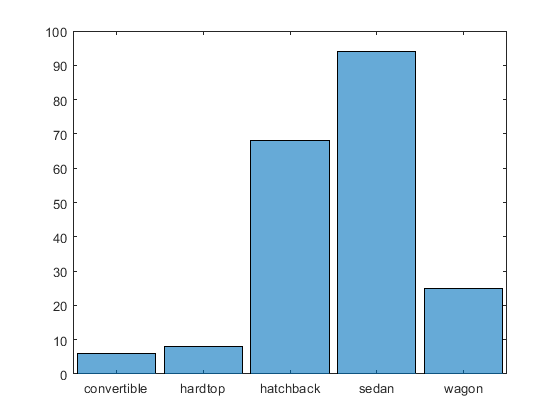

histogram(auto.body_style)

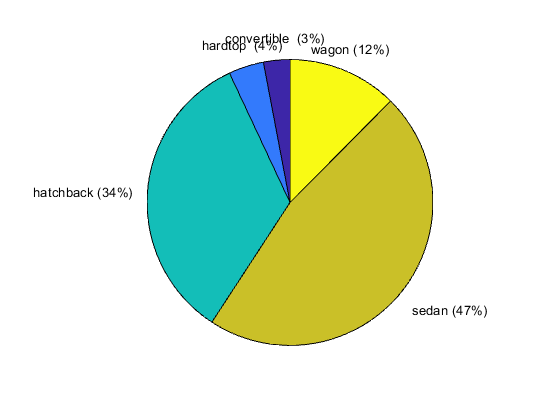

pie(auto.body_style)

## correlation

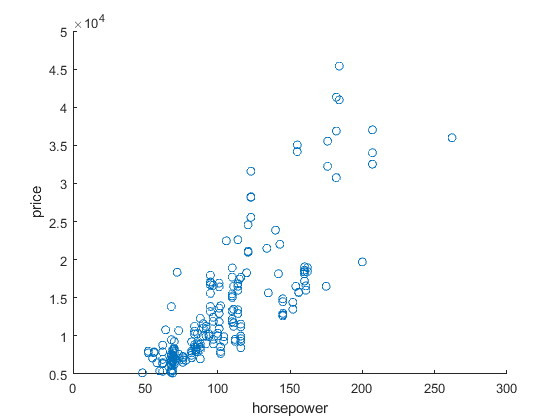

scatter(auto.horsepower,auto.price)
xlabel('horsepower') 
ylabel('price') 

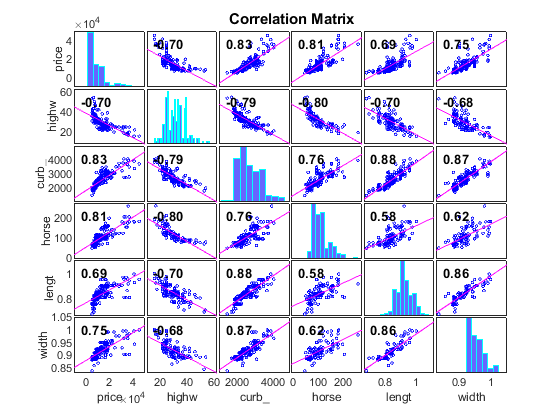


corrplot(auto(:,["price" "highway_mpg","curb_weight" "horsepower" "length","width"]))

## contengincy table

[tbl,chi2,p,labels] = crosstab(auto.drive_wheels,auto.make )

tbl =      3     0     8     0     0     0     2     3     6     8     1     0     3    11     1     4     0     0     0    14     0    11
     0     5     0     3     9    13     0     0    11     0     0    13    15     0     6     0     2     6     7    16    12     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     2     0     0


chi2 = 187.8185

p = 2.4336e-20

labels = 22×2 cell 数组
    {'rwd'     }    {'alfa-romero'  }
    {'fwd'     }    {'audi'         }
    {'4wd'     }    {'bmw'          }
    {0×0 double}    {'chevrolet'    }
    {0×0 double}    {'dodge'        }
    {0×0 double}    {'honda'        }
    {0×0 double}    {'isuzu'        }
    {0×0 double}    {'jaguar'       }
    {0×0 double}    {'mazda'        }
    {0×0 double}    {'mercedes-benz'}
    {0×0 double}    {'mercury'      }
    {0×0 double}    {'mitsubishi'   }
    {0×0 double}    {'nissan'       }
    {0×0 double}    {'peugot'       }
    {0×0 double}    {'plymouth'     }
    {0×0 double}    {'porsche'      }



hm=heatmap(tbl)

hm =   HeatmapChart - 属性:

        XData: {22×1 cell}
        YData: {3×1 cell}
    ColorData: [3×22 double]

  显示 所有属性


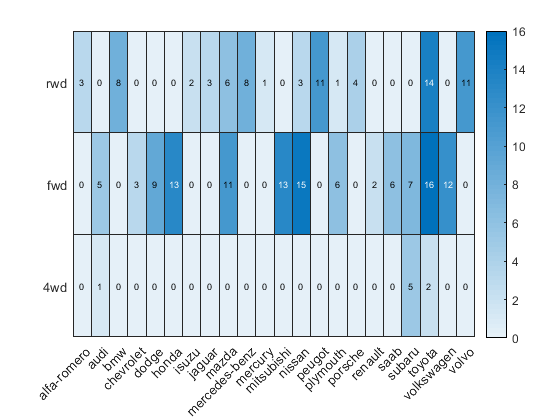

hm.XDisplayLabels = labels(:,2);
hm.YDisplayLabels = labels(1:3,1);

## group box plot

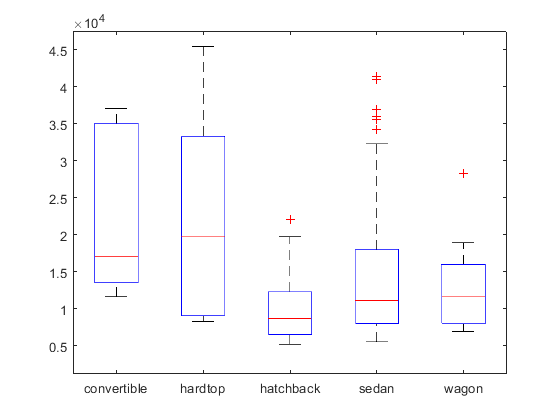

boxplot(auto.price,auto.body_style)

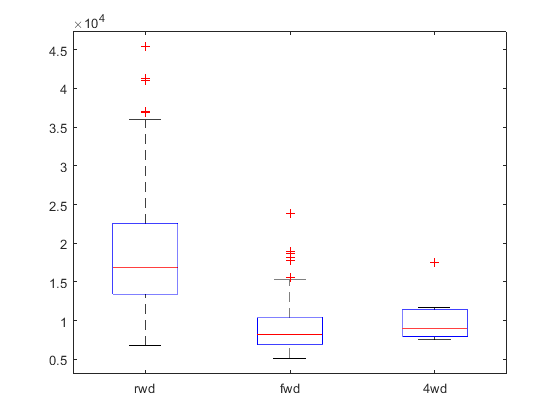


boxplot(auto.price,auto.drive_wheels)